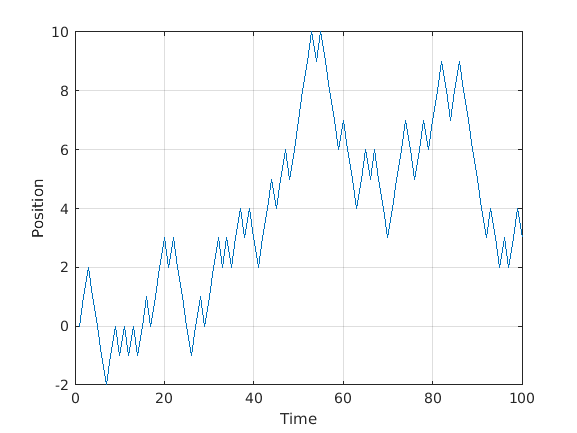

clear x
probability=0.50; %probabilidad de si la decisión es +1 o -1 en Y en el rango de 0 a 1
step=1; %numero de pasos
T=100; %Cantidad de situaciones o tiempo de 0 a 100
x(1)=0; %punto de partida
for i=2:T %loop de conteos
    if (rand > probability) %Si el randomizador es mayor a la probabilidad entonces....
        x(i)=x(i-1)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.5 entonces +1
    else
        x(i)=x(i-1)-step; % de lo contrario -1
    end
end
plot(1:T,x)
grid on
 
xlabel('Time');
ylabel('Position');

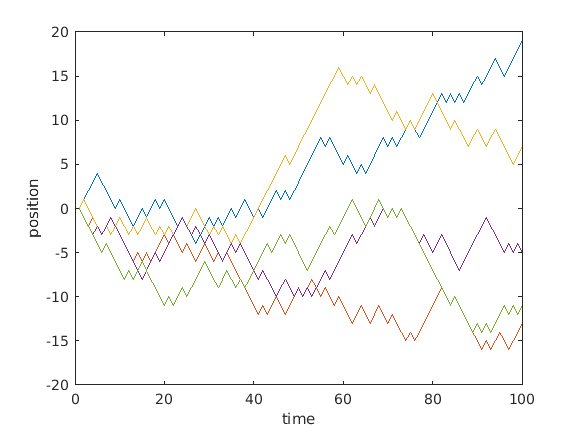

clear x
probability=0.50; %probabilidad de si la decisión es +1 o -1 en Y en el rango de 0 a 1
step=1;%numero de pasos
T=100; %Cantidad de situaciones o tiempo de 0 a 100
for line=1:5 %numero de lineas que estamos graficando 
    x(1,line)=0; %Orden o punto de partida que toma cada linea en el conteo de T; Cuando se grafican todos los valores en tonces x(1,2)=0 sería el nuevo valor
    for i=2:T %loop de conteos
        if (rand > probability) %Si el randomizador es mayor a la probabilidad entonces....
            x(i,line)=x(i-1,line)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.5 entonces +1
        else
            x(i,line)=x(i-1,line)-step; % de lo contrario -1
        end
    end
end
plot(1:T,x)
xlabel('time');
ylabel('position');

clear x
p=rand;%probabilidad de si la decisión es +1 o -1 en Y en el rango de 0 a 1 pero de forma aleatoria
step=1; %numero de pasos
T=100; %Cantidad de situaciones o tiempo de 0 a 100
x(1)=0; %punto de partida
for i=2:T %lopp de conteos
    if (rand > p) %Si el randomizador es mayor a la probabilidad entonces....
        x(i)=x(i-1)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.5 entonces +1
    else
        x(i)=x(i-1)-step; % de lo contrario -1
    end
end
plot(1:T,x)
disp('el valor que tiene la nueva probabilidad es equivalente a:')

el valor que tiene la nueva probabilidad es equivalente a:


disp(p)

    0.2821



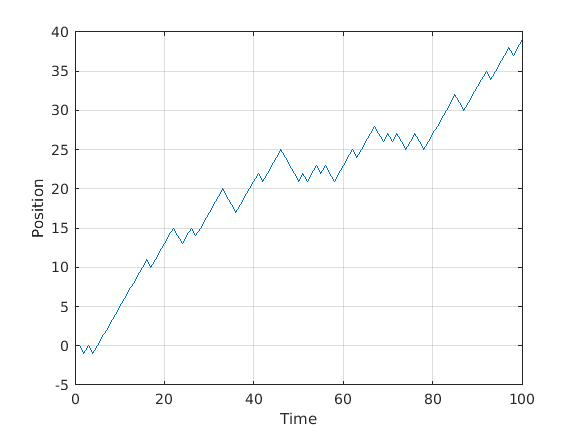

grid on
xlabel('Time');
ylabel('Position');

### **Análisis:**

Al algoritmo presentado pretende simular los "caminos aleatorios" de la siguiente manera.

Para comenzar, la definición de las variables:

- -Se define la variable "p", que define la probabilidad en la que serán acotados los casos explicados más adelante. La variable será generada a través de la función "rand", según la cual, el comportamiento de la gráfica variará.

- -Se define la variable "step", que equivale al valor unitario que será adicionado o restado según la probabilidad que haya sido originada a través de la función "rand".

- -Se devine "T", como el eje x de la gráfica, el cual representa el tiempo de ejecución, simulando que cada "step" desde el valor de partida hasta "T", equivale al paso del tiempo total de ejecución.

#### Explicación de los ciclos "for"

- -El primer bucle for será el encargado de generar las múltiples trayectorias a través de la variable "line", que para este código se ha definido desde 1 hasta 5, siendo que serán graficados 5 caminos aleatorios.

- -El segundo bucle for será el que decida a través de la función "rand" y 2 condiciones, la adición o sustracción del valor inicial de la variable respuesta de la siguiente forma:

1. "rand" genera un valor aleatorio que será comparado con la variable "p", en dado caso de que el valor aleatorio sea mayor a "p", se cumple el primer caso en el que a la variable de partida le será adicionado el valor de "step". En el caso contrario,

2. Si "rand" genera un valor aleatorio menor a "p", cumpliendo el segundo caso, a la variable de partida le será sustraído el valor de "step".

Este bucle for se llevará a cabo hasta que se hayan completado los 100 casos estipulados para "T".

Cuando el bucle interno for termine, el bucle exterior for cambiará repetidas veces hasta generar los múltiples caminos aleatorios según la regla del for interno.

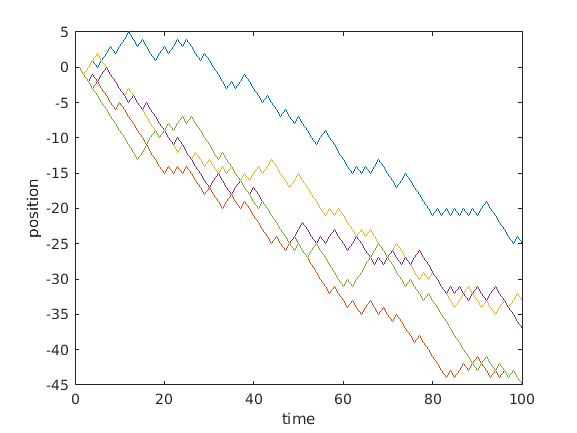

clear x
p=rand; %probabilidad de si la decisión es +1 o -1 en Y en el rango de 0 a 1 pero de forma aleatoria
step=1;%numero de pasos
T=100; %Cantidad de situaciones o tiempo de 0 a 100
for line=1:5 %numero de lineas que estamos graficando 
    x(1,line)=0; %Orden o punto de partida que toma cada linea en el conteo de T; Cuando se grafican todos los valores en tonces x(1,2)=0 sería el nuevo valor
    for i=2:T %loop de conteos
        if (rand > p) %Si el randomizador es mayor a la probabilidad entonces....
            x(i,line)=x(i-1,line)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.5 entonces +1
        else
            x(i,line)=x(i-1,line)-step; % de lo contrario -1
        end
    end
end
plot(1:T,x)
xlabel('time');
ylabel('position');